## Flight Control Law Design and Application 

### Term Project Part III: Lateral Directional Control

**Introduction**

This Matlab livescript is designed for the term project of the course 'Flight Control Law Design and Application'. It comprises all tasks to be done during Part III of the term project. The script is designed such that it will provide you with information, specific tasks, and the possibility to check your progress for yourself. Further, this script will be used by us to verify your results at the end of Part III of the term project. 

**Do's and Don'ts**

In order to use this livescript successfully, you have to fullfill the given **Tasks** (blockwise) in the given order. It is recommended to run the code sections one by one and to valide your results with the implemented checks before advancing. Otherwise, required results for subsequent parts might not be available. Sections can be executed individually with the 'Run Section' Button above.

When running a code section, warnings and error messages might be displayed within this script analog to the usual output in the command window. Use these warnings/errors to correct your solutions if necessary.

In contrast to Part I & II, all of the tasks in this script refer to the **'AircraftModel_6DoF.slx'** model that is provided to you. Nevertheless, all **Tasks** of Part I & II *must be completed before advancing* to the **Tasks** in this script.

In Part III, you will use a new nonlinear aircraft model which simulates the complete six degree of freedom (DoF) motion of the aircraft. The longitudinal motion of the 6DoF aircraft and the former longitudinal motion aircraft that you've worked with are identical. In Part III, you will design controllers for the lateral directional motion (LDM) of the aircraft and augment the already existing flight control laws. Finally, you will obtain a complete flight control system for the nonlinear aircraft model.

**Preparation and Session Start**

This task will prepare Part III of the term project. Futher, this code will run several parameter scripts and will load several variables, structs, etc. into your Matlab workspace. Provided this, the 'AircraftModel_6DoF.slx' model is executable.  

**Task 1: **prepare for Part III of the term project

- copy the "MyTrimStates.m" script from the "2_Model_TrimLinearize" and the "ControlLaws.mat" struct from the "3_LongitudinalControl" folder into the provided "4_6DoFControl" folder

- load all required variables, structs, etc. into your Matlab workspace

- to do so, run this section (keyboard short cut: cntr + enter)

clear
clc

addpath('4_6DoFControl')
run("AircraftParameters.m");
load("ControlLaws.mat")

**Trim and Linearize**

Like within Part II of the project, we intend to design the flight control system based on a (linear) model of the aircraft. Hence, we'll have to trim and linearize the nonlinear 6DoF aircraft model **'AircraftModel_6DoF.slx' **at a specific operation point. Recall the steps taken in the second half of Part I (Tasks 2,3 and 5) to obtain such a model.

**Task 2:** trim the nonlinear 6DoF aircraft model in straight and level flight 

- open the 'AircraftModel_6DoF.slx' model and ensure that it is executable

- start the 'Steady State Manager' and trim the aircraft in straight an level flight

- run the subsequenct code section to recall the desired trim states

- include state and/or input specifications to create the trim state (indicate known (fixed) values by using the check box)

Hint 1: the aircraft's position on earth (Latitude and Longitude) is **not** steady! Hint 2: it might help the solver if the velocity 'v' is not fixed to $0\,m/s$)

- rename the 'Trim Specifications' to 'TrimState_1_6DoF_Spec', the (final) trim report to 'TrimState_1_6DoF_Report' and obtain the operating point 'TrimState_1_6DoF_Op'

- export the specification, the report, and the operating point to your Matlab workspace and save them into a into a single 'MyTrimReport.mat'-file (save it into the '4_6DoFControl' folder)

- open the 'AircraftParameters.m' script from the '4_6DoFControl' folder and modify the entires specifying the trim point to match the trim states of 'TrimState_1_6DoF_Op': type in the values by hand **as precisely as possible** 

run MyTrimStates.m

fprintf(['First Trim State:' '\n' ...
'u   = ' num2str(MyTrimState_1.u) ' ± 0.5 m/s' '\n' ...
'v   = 0 m/s \n' ...
'p   = 0 rad/s \n' ...
'q   = 0 rad/s' '\n' ...
'r   = 0 rad/s \n' ...
'Phi = 0 rad \n'...
'Psi = deg2rad(60) rad \n'...
'Lat = deg2rad(53.58715) rad \n'...
'Lon = deg2rad(9.89862) rad \n'...
'Alt = ' num2str(MyTrimState_1.Alt) ' ± 5 m' '\n'])

First Trim State:
u   = 130 ± 0.5 m/s
v   = 0 m/s 
p   = 0 rad/s 
q   = 0 rad/s
r   = 0 rad/s 
Phi = 0 rad 
Psi = deg2rad(60) rad 
Lat = deg2rad(53.58715) rad 
Lon = deg2rad(9.89862) rad 
Alt = 4000 ± 5 m


clear MyTrimState_1 MyTrimState_2 MyTrimState_3

**Task 3:** linearize the nonlinear 6DoF model at the 'TrimState_1_6DoF_Op'

- load the 'TrimState_1_Op' operating point into your Matlab workspace

- open the 'Model Linearizer' and specify the inputs and outputs of the linear model to be obtained to be 'Root Level Inports and Outports'

- specify the 'Operating Point' to be 'TrimState_1_6DoF_Op'

- within 'More Options' untag the setting "Exclude non-minimal states from linear models using block reduction"

- further enable state ordering and define the following state order:  u, v, w, p, q, r, Phi, Theta, Psi, Lat, Lon, Alt, de, da, dr, X_P1, X_P2 

- linearize the model and rename the obtained linear model to 'Linear6DoFModel', export it to your Matlab workspace (drag & drop)

- use the subsequent **'Check'** section to check the state names, input names and output names of the linear model

- In case some (output) names include an additional path (e.g. 'AircraftModel_6DoF/Psi'), shorten them to the variable names only

- add units to *every input, output and state*: (use '-' for normalized signals)

- save the linear model into a new .mat-file named 'TrimState_1_Linear6DoFModel.mat' (save it into the '4_6DoFControl' folder)

**Check:**

load MyTrimReport
TrimState_1_6DoF_Report.display

TrimState_1_6DoF_Report =  Operating point search report for the Model AircraftModel_6DoF.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
    Min          x          Max        dxMin        dx         dxMax   
___________ ___________ ___________ ___________ ___________ ___________
                                                                       
(1.) da
   -Inf     -1.8469e-16     Inf          0      2.0398e-18       0     
(2.) de
   -Inf      -0.10422       Inf          0      4.4409e-16       0     
(3.) dr
   -Inf     -2.0026e-16     Inf          0      1.0504e-18       


load TrimState_1_Linear6DoFModel.mat
Linear6DoFModel.StateName

ans = 17×1 cell array
    {'u'    }
    {'v'    }
    {'w'    }
    {'p'    }
    {'q'    }
    {'r'    }
    {'Phi'  }
    {'Theta'}
    {'Psi'  }
    {'Lat'  }
    {'Lon'  }
    {'Alt'  }
    {'de'   }
    {'da'   }
    {'dr'   }
    {'X_P1' }
    {'X_P2' }


Linear6DoFModel.StateUnit

ans = 17×1 cell array
    {'m/s'  }
    {'m/s'  }
    {'m/s'  }
    {'rad/s'}
    {'rad/s'}
    {'rad/s'}
    {'rad'  }
    {'rad'  }
    {'rad'  }
    {'rad'  }
    {'rad'  }
    {'m'    }
    {'rad'  }
    {'rad'  }
    {'rad'  }
    {'N'    }
    {'N'    }


Linear6DoFModel.InputName

ans = 4×1 cell array
    {'cmd_de'}
    {'cmd_da'}
    {'cmd_dr'}
    {'cmd_dt'}


Linear6DoFModel.InputUnit

ans = 4×1 cell array
    {0×0 char}
    {0×0 char}
    {0×0 char}
    {0×0 char}


Linear6DoFModel.OutputName

ans = 16×1 cell array
    {'p'    }
    {'q'    }
    {'r'    }
    {'u'    }
    {'v'    }
    {'w'    }
    {'Phi'  }
    {'Theta'}
    {'Psi'  }
    {'Alt'  }
    {'n_y'  }
    {'n_z'  }
    {'gamma'}
    {'Chi'  }
    {'alpha'}
    {'beta' }


Linear6DoFModel.OutputUnit

ans = 16×1 cell array
    {'rad/s'}
    {'rad/s'}
    {'rad/s'}
    {'m/s'  }
    {'m/s'  }
    {'m/s'  }
    {'rad'  }
    {'rad'  }
    {'rad'  }
    {'m'    }
    {'-'    }
    {'-'    }
    {'rad'  }
    {'rad'  }
    {'rad'  }
    {'rad'  }


clear ans

**Check:** Use this section to check whether the step resonses are reasonable. Note that the engines on the 'VFW 614' aircraft are located above the wings, i.e. in negative $z_f$ - direction wrt. the center of gravity. Further note, that a negative step is applied to the elevator. The right aileron and the rudder are deflected positively.

load TrimState_1_Linear6DoFModel.mat
checklinearmodel(Linear6DoFModel,6) % Note that the inputs deviations are scaled to -3° elevator deflection, 3° aileron deflection, 5° rudder deflection and 0.2 thrust lever command

**Decoupled Longitudinal and Lateral Directional Motion**

Recall from chapter 10 in the lecture notes that the longitudinal dynamics and the lateral directional dynamics of the aircraft are in fact independent of each other. This implies that the modal responses of the longitudinal dynamics, i.e., the phugoid mode and the short period mode, are not excited by an aileron (or rudder) deflection. Likewise, the dynamic modes of the lateral directional motion (we'll take a closer look on them below) are not excited by a deflection of the elevator. Take a look at the pole/zero-maps for three different transfer functions, e.g., from aileron input $da$ to roll rate $p$. For an aileron input, the poles related to the phugoid mode and those related to the short period mode are cancelled by zeros, i.e., these modes do not contribute to the aircraft's motion. Note that all three transfer functions excite either the longitudinal or lateral directional dynamics only. 

**Task 4:** check the decoupling by investigating the pole/zero-maps

- select each transfer function from the drop down menu and take a look at the pole/zero-maps

- check whether the poles related to the phugoid and short period mode are cancelled for $P(s)_{p \leftarrow da}$ and $P(s)_{r \leftarrow dr}$

- check wether all poles *except* for those related to the phugoid and short period mode are cancelled for $P(s)_{q \leftarrow de}$

- are there differences between the pole/zero-maps of $P(s)_{p \leftarrow da}$ and $P(s)_{r \leftarrow dr}$ ? If no, why not? If yes, what do they indicate?

load TrimState_1_Linear6DoFModel.mat
io = {'q','cmd_de'};
opt = pzoptions;
opt.Xlim = [-6 0.5];
figure(402); clf; pzmap(Linear6DoFModel(io(1),io(2)),opt),
clear opt io

**State Space Transformation and LDM Dynamic Modes**

From the previous section we saw that the longitudinal and lateral directional dynamics are in fact decoupled. Recall that we are interested in the lateral directional dynamics in Part III. We thus intend to obtain a suitable model reflecting these lateral directional dynamics by reducing the full order 6DoF linear model. This model will then be transformed and augmented and finally used for model based controller design.

**Task 5:** create a lateral directional motion model

- uncomment and then augment the code section below

- select the inputs and outputs of the 'Linear6DoFModel' belonging solely to the lateral directional motion, i.e., the roll rate $p$, yaw rate $r$, sway velocity $v$, etc. - hint: the reduced model shall have two inputs and eight outputs

- remove all states related to the longitudinal motion as well as the position states (Lat,Lon) from the newly created 'LinearLatModel' using the `modred` command; decide whether you need to apply truncation or residualization - hint: the reduced model shall have seven states

We further intend to change the state space, i.e., we exchange the sway velocity $v$ with the angle of sideslip $\beta$ to be aligned with the lecture. Recall from the lecture, that for small angles $\beta \approx v/V_\text{a}$ is a good approximation. 

- use the `ss2ss` command to perform a state space transformation that exchanges the sway velocity $v$ by the angle of sideslip $\beta$ (recall **Task 6** from 'FCDA_TermProject_Part_I_2.mlx')

- append the LinearLatModel with actuator specific time delays (see the 'Actuators.Delays'-struct in your Matlab workspace) using the code of **Task 4** from 'FCDA_TermProject_Part_II.mlx' as a guideline

- redefine the state and input names and define the state and input units

- check the reduced linear model using the subsequent check section

- **save the changes you've made within this livescript**

- save the transformed linear model to 'TrimState_1_Linear**Lat**Model.mat'

load TrimState_1_Linear6DoFModel
% --------------------start of your code -------------------------- %

LinearLatModel = Linear6DoFModel({'p', 'r', 'v', 'Phi', 'Psi', 'Chi','beta', 'n_y'},{'cmd_da', 'cmd_dr'}); % select inputs/outputs of correpsonding to the lateral directional motion
LinearLatModel = modred(LinearLatModel,[1 3 5 8 10 11 12 13 16 17], 'truncation'); % remove states not related to the lateral directional motion
V_a = sqrt(TrimState_1_6DoF_Report.states(1).x^2+TrimState_1_6DoF_Report.states(2).x^2+TrimState_1_6DoF_Report.states(3).x^2);
LinearLatModel = ss2ss(LinearLatModel,blkdiag(1/V_a,1,1,1,1,1,1)); % perform state space transformation
%Actuators.Act_a.B = -Actuators.Act_a.A;
%Actuators.Act_r.B = -Actuators.Act_r.A;
%Td = exp(-tf('s')); 
appendDyn = append(Actuators.Act_a, Actuators.Act_r);
%LinearLatModel = LinearLatModel*appendDyn;
%LinearLatModel = LinearLatModel*blkdiag(Actuators.Act_a, Actuators.Act_r); % add time delays to both inputs

% --------------------end of your code ---------------------------- %

**Check  **The reduced model 'LinearLatModel' is correct if the magnitudes of the Bode plot perfectly match the ones of the 'Linear6DoFModel' (for the selected input/output channels). Note that the actuator time delays influence the phase!

load TrimState_1_LinearLatModel
LinearLatModel.StateName

ans = 7×1 cell array
    {0×0 char}
    {0×0 char}
    {0×0 char}
    {0×0 char}
    {0×0 char}
    {0×0 char}
    {0×0 char}


LinearLatModel.StateUnit

ans = 7×1 cell array
    {0×0 char}
    {0×0 char}
    {0×0 char}
    {0×0 char}
    {0×0 char}
    {0×0 char}
    {0×0 char}


LinearLatModel.InputName

ans = 2×1 cell array
    {'cmd_da'}
    {'cmd_dr'}


LinearLatModel.InputUnit

ans = 2×1 cell array
    {0×0 char}
    {0×0 char}


LinearLatModel.InputDelay

ans =      0
     0


[Actuators.Delays.tau_da Actuators.Delays.tau_dr]

ans =     0.0400    0.0400


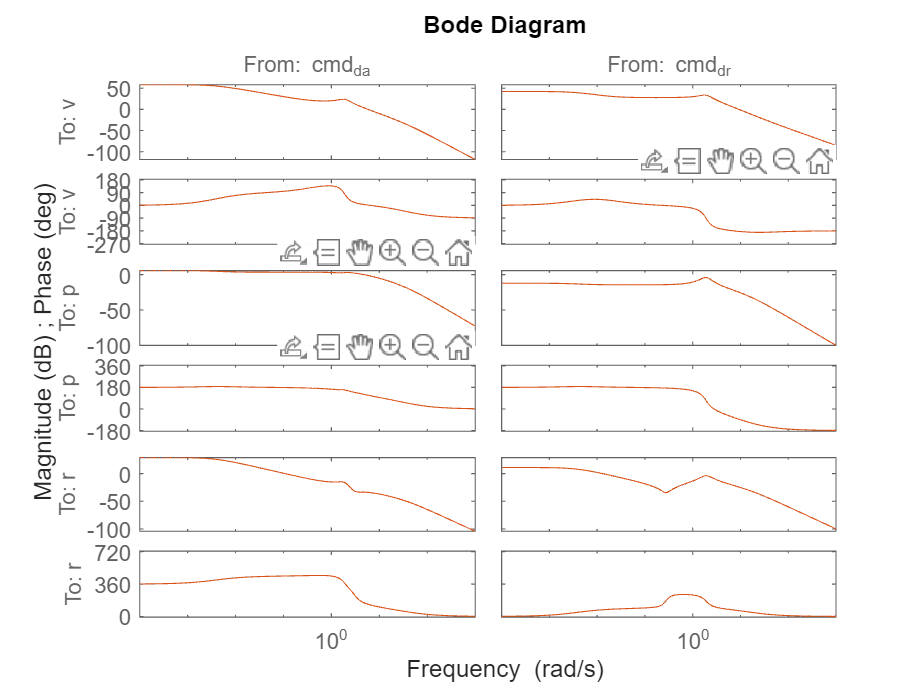

clear ans
figure(403); clf; bode(Linear6DoFModel({'v','p','r'},{'cmd_da','cmd_dr'}),LinearLatModel({'v','p','r'},{'cmd_da','cmd_dr'}))

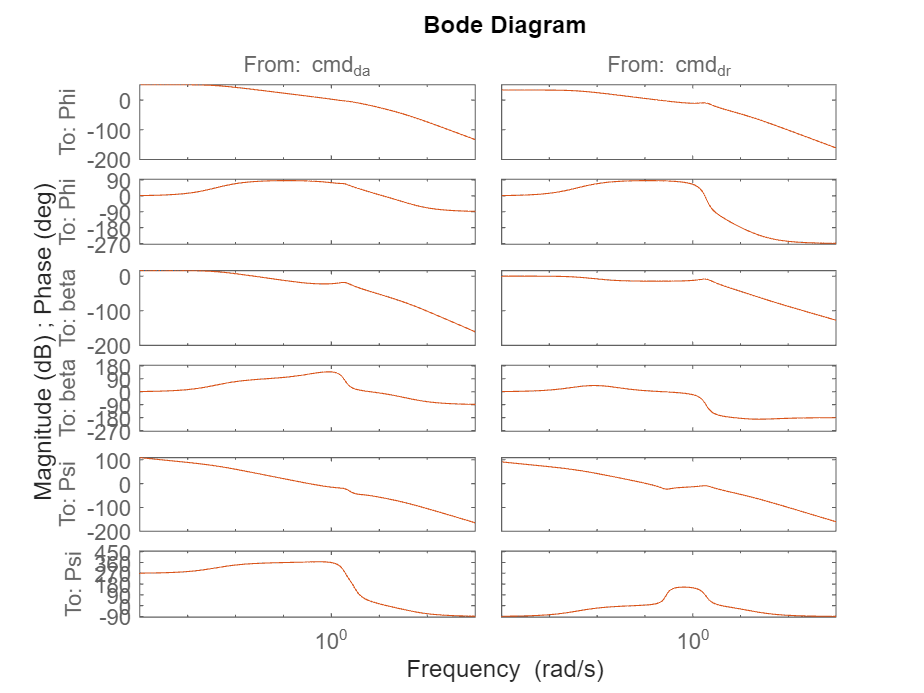

figure(404); clf; bode(Linear6DoFModel({'Phi','beta','Psi'},{'cmd_da','cmd_dr'}),LinearLatModel({'Phi','beta','Psi'},{'cmd_da','cmd_dr'}))

**Phasor Diagrams and Mode Responses**

Like in Part I ($2nd$ half) , we want to create a second linear model named 'LinearLatModel_Phasor' to create phasor plots that are easier to interpret. We thus temporarily change the units of the angles $\beta$ and $\Phi
$ from 'rad' to 'deg' and the units of the roll rate $p$ and yaw rate $r$ from 'rad/s' to 'deg/s'.

**Task 6:** create a second transformed linear model for the subsequent phasor plots

- load the 'LinearLatModel' into your Matlab workspace

- uncomment and augment the code section below to further reduce the 'LinearLatModel' 

- remove the actuator dynamics as well as the 'Psi' state using the `modred` command: decide whether to use truncation or residualization individually

- perform a state space transformation using the `ss2ss` command similarly to **Task 7** of 'FCDA_TermProject_Part_I_2.mlx' to achieve the desired unit conversion

- redefine the state names and define the (**new**) state units

- save the 'LinearLatModel_Phasor' model into 'TrimState_1_LinearLatModel_Phasor.mat'

load TrimState_1_LinearLatModel.mat
% --------------------start of your code -------------------------- %

LinearLatModel_Phasor = modred(LinearLatModel, [5],'truncation'); %State Reduction of Psi
%LinearLatModel_Phasor = modred(LinearLatModel_Phasor,[6 7] 'MatchDC'); %State Reduction of Actuator Dynamics
LinearLatModel_Phasor = ss2ss(LinearLatModel_Phasor, blkdiag(180/pi,180/pi,180/pi,180/pi,180/pi,180/pi)); % transforms the state space of the linear aricraft model.

% --------------------end of your code ---------------------------- %
damp(LinearLatModel_Phasor)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  3.82e-03                -1.00e+00       3.82e-03        -2.62e+02    
 -4.82e-01 + 1.85e+00i     2.53e-01       1.91e+00         2.07e+00    
 -4.82e-01 - 1.85e+00i     2.53e-01       1.91e+00         2.07e+00    
 -3.83e+00                 1.00e+00       3.83e+00         2.61e-01    
 -1.60e+01                 1.00e+00       1.60e+01         6.25e-02    
 -3.64e+01                 1.00e+00       3.64e+01         2.75e-02    


The lateral directional dynamics typically comprise three modes: the spiral mode, the roll subsidence mode, and the dutch roll mode. The spiral mode is the 'slowest' mode that couples the roll motion with the yaw motion. More precisely, it states that a positive (negative) bank angle leads to a positive (negative) yaw rate. It thus allows the pilot to change the direction of flight by banking the aircraft. For many aircraft, the spiral mode is stable: after an initial excitation, the aircraft will either reach a steady state with constant bank angle and yaw rate (corresponding eigenvalue $\lambda_{\text{sl}}=0$) or both, $\Phi$ and $r$, will decrease and finally return to zero ( $\lambda_{\text{sl}}<0$, looking on the horizontal plane $x_g/y_g$, the aircraft flies a loosening spiral). Note, however, that the spiral mode can be unstable (indicated by a positive eigenvalue $\lambda_{\text{sl}}>0$). The aircraft then flies a tightening spiral with possibly fatal consequences. In many cases however, the spiral mode is so 'slow' that appropriate control action can be taken by the pilot to easily stabilize the aircraft. The roll subsidence mode can be considered as the damping of the rolling motion. That is, the eigenfrequency of the roll subsidence mode is an indicator for the aircrafts inherent damping of its own roll motion - a 'fast' roll subsidence mode indicates that the roll rate $p$ is quickly reduced to zero and prevents the bank angle from building up over time if no additional control action is applied. The dutch roll mode couples the roll and yaw motion such that the aircraft performs an oscillatory motion. It is typically stable but lightly damped, leading to pilot and/or passenger discomfort.

**Task 7:** link the dynamic modes to the corresponding eigenvalues

- load the linear model 'LinearLatModel_Phasor' into your workspace

- uncomment the code section below

- link the spiral mode, the dutch roll mode and the roll subsidence mode to the corresponding eigenvalues of the system

- plot the poles into the complex plane using the provided function `polemap_lat` (this function is not part of Matlab and written for this class. Matlab has the function `pzmap` to generate a similar plot.)

- augment the code to plot the phasor diagrams and the modal responses of the three lateral directional modes using the provided `phasor_lat` and `mode_resp_lat` functions

- **save the changes you've made within this livescript**

Compare your results for the 'VFW 614' aircraft with the plots of the 'Airbus A330 like' aircraft in the lecture notes. --> Are your results reasonable? Compare the damping ratios and the natural frequencies of the modes for both aircraft: are the individual dynamic mode of the 'VFW 614' aircraft 'faster' or 'slower' than the ones of the 'Airbus A330 like' aircraft? What can be said about the spiral mode? Does the 'VFW 614' show similar phasor diagrams and mode responses as the 'Airbus A330 like' aircraft? Does the modal response of the spiral mode match your expectation? Note the time scale of the spiral modes modal response: do you consider this mode controllable by a pilot? 

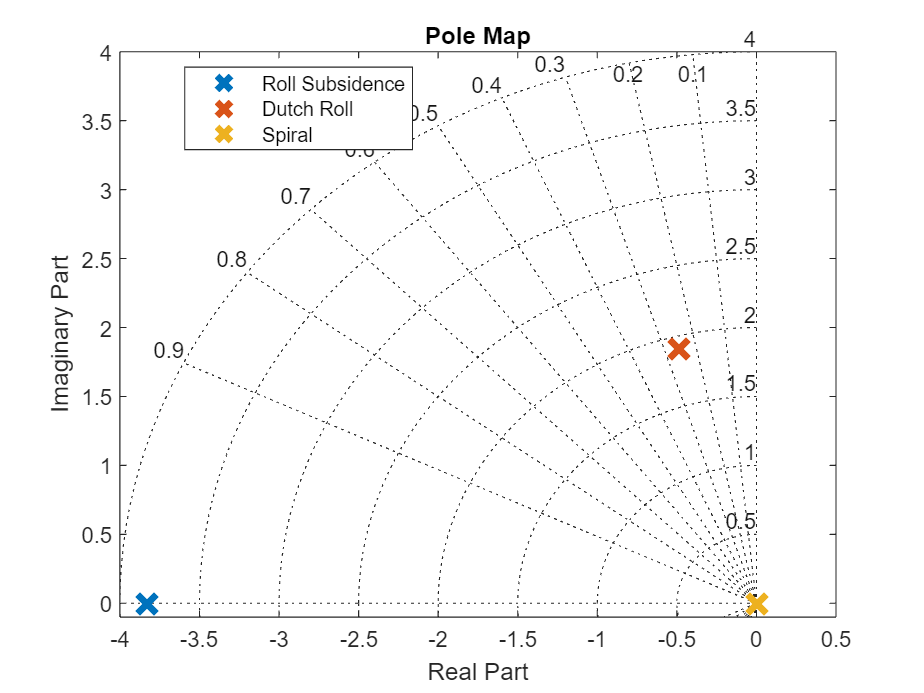

load TrimState_1_LinearLatModel_Phasor
% --------------------start of your code -------------------------- %

idx_rs = [1]; % e.g. idx_rs = [3] --> indice(s) of the eigenvalue(s) within the vector of eigenvalues corresponding to the roll subsidence mode (rs) 
idx_dr = [2 3]; % indice(s) of the eigenvalue(s) within the vector of eigenvalues corresponding to the dutch roll mode (dr)  
idx_sl = [4]; % indice(s) of the eigenvalue(s) within the vector of eigenvalues corresponding to the spiral mode (sl)
% 
% % Indices of the outputs corresponding to beta, p, r and Phi
idx_outputs(1) = find(ismember(LinearLatModel_Phasor.OutputName,'beta')); idx_outputs(2) = find(ismember(LinearLatModel_Phasor.OutputName,'p'));
idx_outputs(3) = find(ismember(LinearLatModel_Phasor.OutputName,'r')); idx_outputs(4) = find(ismember(LinearLatModel_Phasor.OutputName,'Phi'));

figure(405); clf;
polemap_lat(LinearLatModel_Phasor, idx_rs, idx_dr, idx_sl)

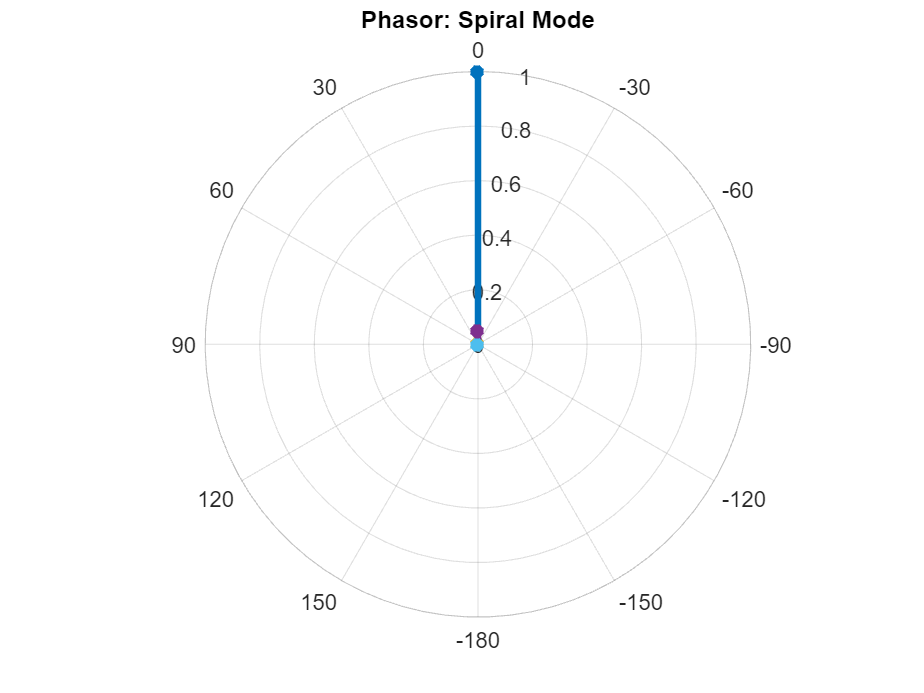

figure(410); clf;
phasor_lat(LinearLatModel_Phasor, idx_sl), title('Phasor: Spiral Mode')

figure(411); clf;
mode_resp_lat(LinearLatModel_Phasor, idx_sl, [-1 1.5]), title('Time Response: Spiral Mode')

Index in position 2 is invalid. Array indices must be positive integers or logical values.

Error in mode_resp_lat (line 18)
X = real(X(:,idx_outputs)); % take only real part of the outputs of interest, i.e. the vector [7 2 3 4] picks the desired outputs of the model (see 'OutputNames' of the model) and changes the order

figure(412); clf;
phasor_lat(), title('Phasor: Dutch Roll Mode')
figure(413); clf;
mode_resp_lat(LinearLatModel_Phasor, idx_dr,[-0.6 0.5]), title('Time Response: Dutch Roll Mode')
figure(414); clf;
phasor_lat(LinearLatModel_Phasor, idx_rs), title('Phasor: Roll Subsidence Mode')
figure(415); clf;
mode_resp_lat(LinearLatModel_Phasor,idx_rs,[-1 0.3]), title('Time Response: Roll Subsidence Mode')

% --------------------end of your code ---------------------------- %

**Check:**

lambda = eig(LinearLatModel_Phasor);
fprintf(['Dutch Roll Mode:' '       Spiral Mode:' '       Roll Subsidence Mode:' '\n' ...
        num2str(lambda(idx_dr(1))) '       ' num2str(lambda(idx_sl(1))) '          ' num2str(lambda(idx_rs)) '\n' ...
        num2str(lambda(idx_dr(2)))])
clear lambda

**Stability Augmentation System I**

Recall from the lecture and Part II that the handling qualities of the aircraft are important. In Part II, you designed a SAS that favorably modified the dynamics of the aircraft to achieve good handling qualities. Of course, the concept of handling qualities is not limited to the longitudinal motion alone but can also be applied to the lateral directional motion. There are several specifications that can be used as a guideline for the LDM. In this term project, we choose the specifications of *Michael Cook - Flight Dynamics Principles, 3rd Edition, Oct 2012, Butterworth-Heinemann*. First, we have to check whether the handling qualities of our aircraft are acceptable. We do this by assessing the dynamics of the three modes of the LDM. We consider the 'VFW 614' aircraft to be an aircraft of class III (large, low to medium manoeverability) and only consider non-terminal flight phases (we do not consider the start or landing phase).

**Task 8:** check the dynamics of the LDM w.r.t. the handling qualities criteria of *Cook*

- load the linear model 'LinearLatModel' into your workspace

- use the `damp` command to check the eigenfrequencies, damping ratios and time constants of the spiral mode, the dutch roll mode and the roll sibsidence mode

- check whether the aircraft dynamics fulfill the requirements for Level 1 handling qualities using the tables and the figure shown below

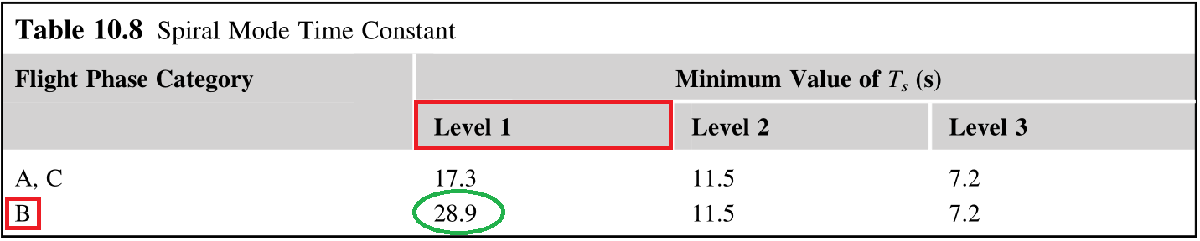

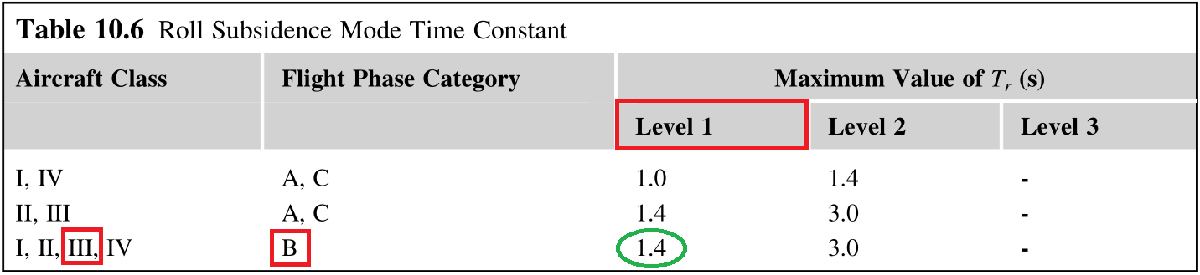

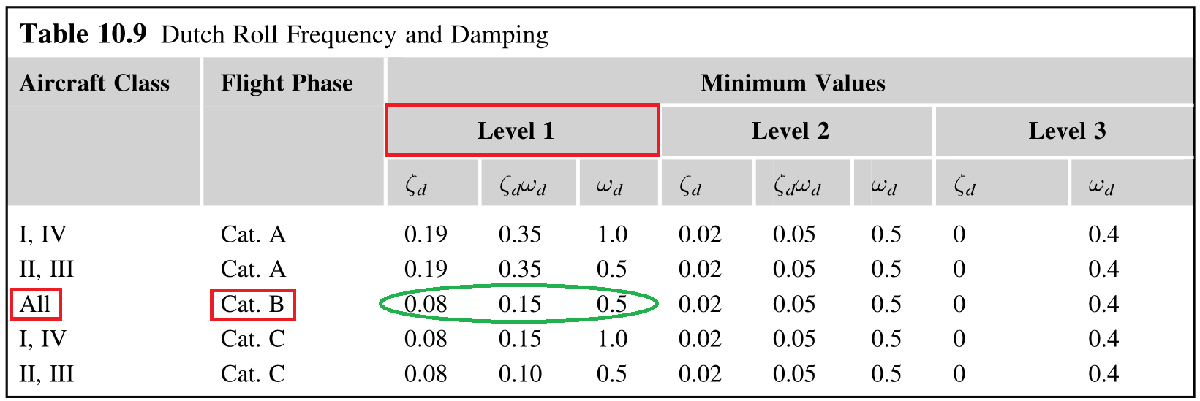

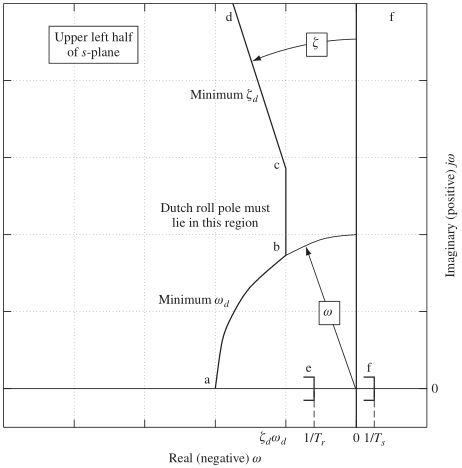

Regardless of the outcome of the dutch roll mode handling qualities assessment, take a look at a step response exciting the dutch roll mode via rudder deflection (run the code below). The oscillatory behaviour of the dutch roll mode is evident and is uncomfortable for the pilots and the passengers. We thus intend to implement a SAS to increase the damping ratio of the dutch roll mode. Recall from the lecture that deflecting the rudder based on yaw rate feedback - a yaw damper - is a suitable solution to achieve this. 

load TrimState_1_LinearLatModel
[sig,time] = step(LinearLatModel({'r','p'},'cmd_dr')*deg2rad(5),15);
figure(420); clf; subplot(2,1,1), plot(time,180/pi.*sig(:,1),'LineWidth',2), grid, title('Step Response from input: $\Delta \delta_r$',"Interpreter","latex","FontSize",14), ylabel('Output: $\tilde{r}$', "Interpreter","latex","FontSize",13)
                  subplot(2,1,2), plot(time,180/pi.*sig(:,2),'LineWidth',2), grid, xlabel('Time in s'), ylabel('Output: $\tilde{p}$', "Interpreter","latex","FontSize",13); clear sig time;

**Task 9:** design a SAS feedback controller for the LDM

- load the 'LinearLatModel' into your workspace

- use the `controlSystemDesigner` command to investigate the transfer function from rudder input to yaw rate (edit the control architecture within the 'Control System Designer' app)

Since the yaw rate measurement is corrupted by noise, we include a low pass filter $F(s) = 1/s+\omega_{\text{lp}}$ to reduce the noise level of the feedback signal. The filtered yaw rate is then processed by the yaw damper. Recall from the lecture that, in addition to the filter, a so called washout filter $F_{\text{wo}} = s/s+\omega_{\text{wo}}$ must be included. This washout filter effectively switches off the yaw damper for low yaw rates which are desired (and required) during a commanded turn of the aircraft. Otherwise the yaw damper will "fight against" the intended turn of the aircraft. We can add both, the lowpass filter and the washoutfilter, during the design within the 'Control System Designer'.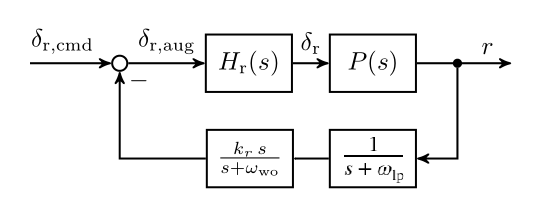

- add the lowpass filter by placing a pole and set the filter bandwidth to $\omega_\text{lp} = 30\,\text{rad/s}$

- include the washout filter by adding a differentiator (a zero at $\omega=0$) and define the washoutfilter bandwidth to $\omega_{\text{wo}} \approx \Re(\lambda_{\text{DR}})$

- modify the dutch mode pole location by adjusting the feedback gain $k_r$ ('drag and drop' within the 'Root Locus Editor')

- try to achieve a dutch roll damping ratio of $\zeta_\text{dr}=0.7$ - note that minor deviations are insignificant as this is a qualitative approach and model uncertainties are inevitable

- keep an eye on the pole related to the roll subsidence: do you consider an additional roll damper necessary to fulfill the requirements for level 1 handling qualities? If not, what are appropriate means to account for this problem?

- keep an eye on the pole related to the spiral mode: Is the spiral mode 'slow' enough to fulfill the requirements for level 1 handling qualities? If not, what are appropriate means to account for this problem?

- read off the controller 'C' and define the controller 'F_r' using the subsequent code section

- define input/output names and units for the state space model 'F_r' - define the state names to 'Kyaw'

- **save the augmented "ControlLaws.mat" and the changes you've made within this livescript**

load("ControlLaws.mat")
% --------------------start of your code -------------------------- %

% omega_lp = ...;  % bandwidth of the lowpass filter
% omega_wo = ...;  % bandwidth of the washout filter
% kr       = ...;  % gain of the yaw damper
% 
% s = tf('s');
% F_r = zpk(kr*...)  % compute the transfer function of the complete feedback path (lowpass filter, washout filter, yaw damper gain)

% --------------------end of your code ---------------------------- %

% augment "ControlLaws" struct
ControlLaws.LatDirMot.SAS.kr = kr;
ControlLaws.LatDirMot.SAS.omega_wo = omega_wo;
ControlLaws.LatDirMot.SAS.omega_lp = omega_lp;
ControlLaws.LatDirMot.SAS.F_r = ss(F_r);
clear F_r kr omega_lp omega_wo

**Task 10: **close the SAS feedback loop and compare the results

- close the SAS feedback loop for the 'LinearLatModel' using the `feedback` command - make sure that only the correct feedback path is closed!

- name the newly created model 'LinearLatModel_SAS_1' and save it to 'TrimState_1_LinearLatModel_SAS_1.mat'

- compare the pole locations of all three LDM modes for the open loop 'LinearLatModel', the 'LinearLatModel_SAS_1' with the help of the subsequent check section - Note that a $2^{nd}$ order Padé approximation is applied to approximate the systems time delay

- compare the aircraft response to rudder and aileron step inputs using the subsequent check section

**Check**

load TrimState_1_LinearLatModel_SAS_1

ControlLaws.LatDirMot.SAS.F_r
clear ans

damp(LinearLatModel)
damp(pade(LinearLatModel_SAS_1,2))
figure(421); clf; lat_compare(LinearLatModel,LinearLatModel_SAS_1)

**Stability Augmentation System II: Aileron-Rudder-Interconnection**

Once again recall the aircrafts step response to rudder and aileron deflection. Note that a rudder deflection causes an additional rolling moment which in turn causes a constant non-zero roll rate $p$. Hence, if the pilots intent is a pure yaw motion, the rudder input inevitably requires a simultaneous aileron deflection of approriate amplitude to counter the additional rolling moment. To reduce workload for the pilot and thus ease handling, a so called *aileron-rudder-interconnection* (ARI) can be implemented. The ARI automatically deflects the aileron such that the induced roll moment due to a commanded rudder deflection is countered. The yaw motion is thus further decoupled from the roll motion. Another benefit of an ARI is to achieve a "coordinated turn" in which the sideslip angle is close to $\beta = 0$ and the aerodynamic drag is reduced. In order to achieve this, the ARI can be designed such that the effect of an aileron deflection on the sideslip angle is reduced via a simultaneous rudder deflection.

**Task 11:** reduce the influence of rudder deflection on roll rate $p$

- load the 'LinearLatModel_SAS_1' model into your workspace

- uncomment the code section below

- use the `freqresp` command to compute the magnitudes of $P(s)_{p \leftarrow dr}$ and $P(s)_{p \leftarrow da}$ at zero frequency (to avoid stability issues use $\omega = 0.0001\,\text{rad/s}$ instead) 

- compute the crossfeed term $B_{da \leftarrow dr}$ according to section 11.4 in the lecture notes - note that $B_{da \leftarrow dr}$ must be real-valued

- **save the changes you've made within this livescript**

load TrimState_1_LinearLatModel_SAS_1
% --------------------start of your code -------------------------- %

% mag_Ppdr = ...; % magnitude of P(s)_p<--dr at w=0
% mag_Ppda = ...; % magnitude of P(s)_p<--da at w=0
% Bdadr    = ...  % crossfeed gain: additional aileron deflection due to rudder deflection command

% --------------------end of your code ---------------------------- %

**Task 12:** reduce the influence of aileron deflection on the sideslip angle ("coordinated turn") 

- uncomment the code section below

- use the `freqresp` command to compute the magnitudes of $P(s)_{\beta \leftarrow dr}$ and $P(s)_{\beta \leftarrow da}$ at the dutch roll frequency $\omega_\text{dr}$

- compute the crossfeed term $B_{dr \leftarrow da}$ according to section 11.4 in the lecture notes - note that $B_{dr \leftarrow da}$ must be real-valued

- compute the ARI matrix and save it within the struct "ControlLaws.LatDirMot.SAS.ARI"

- save the augmented "ControlLaws" struct

- create a new linear model 'LinearLatModel_SAS' that comprises the ARI - decide whether to multiply the ARI to the 'LinearLatModel_SAS_1' from the left or the right

- redefine the input names and units of the newly created model

- check the effect of the ARI by running the subsequent check section - does the ARI show similar effects as the one for the 'A330 like' aircraft of the lecture notes?

- save the 'LinearLatModel_SAS' to 'TrimState_1_LinearLatModel_SAS.mat'

- **save the changes you've made within this livescript**

% --------------------start of your code -------------------------- %

% mag_Pbetadr = ...; % magnitude of P(s)_beta<--dr at w=omega_dr
% mag_Pbetada = ...; % magnitude of P(s)_beta<--da at w=omega_dr
% Bdrda       = ...  % crossfeed gain: additional rudder deflection due to aileron deflection command
% 
% ControlLaws.LatDirMot.SAS.ARI = ...;
% LinearLatModel_SAS = ...;
% LinearLatModel_SAS.InputName = {...};
% LinearLatModel_SAS.InputUnit = {...};

% --------------------end of your code ---------------------------- %
clear mag_Ppdr mag_Ppda mag_Pbetadr mag_Pbetada Bdadr Bdrda

**Check**

load TrimState_1_LinearLatModel ; load TrimState_1_LinearLatModel_SAS_1 ; load TrimState_1_LinearLatModel_SAS
figure(422); clf; lat_compare(LinearLatModel,LinearLatModel_SAS_1,LinearLatModel_SAS)

**Augment Nonlinear 6DoF Simulink Model**

We use the nonlinear 6DoF Simulink model to investigate the performance of the flight control system. In order to do so, we have to augment the provided 'AircraftModel_6DoF.slx'.

**Task 13:** augment the 6DoF Simulink model 

- open the 'AircraftModel_6DoF.slx' model and the 'Auxiliary_Models.slx' model

- include multiple blocks to reach the state as shown in the figure below:

- remove all 'in' ports and 'out' ports from the model

- add 'Aero Noise' and 'Measurement Noise' from the 'Auxiliary_Models.slx' model to the 6DoF model

- add the 'Flight Controls' block from the 'Auxiliary_Models.slx' model 

- **exchange** the 'Longitudinal Control Laws' subsystem with your control laws designed in Part II

- add the 'Test Sequences' subsystem from the 'Auxiliary_Models.slx' model and create a signal 'Inp' as shown in the figure below - use a 'mux' block from the Simulink library and connect the 'Inp' signal to the 'Flight Controls' subsystem

- uncomment the 'To Workspace' block that computes the 'out.inp_check' struct (uncomment the block with the shortcut 'cntr' + 'shift' + 'x') and connect it to the 'Inp' signal

- connect the wind signals from the 'Test Sequences' subsystem to the appropriate wind inputs

- optional: add the 'Visualization' block from the 'Auxiliary_Models.slx' model

- **save** the augmented model **to a new file** named 'AircraftModel_6DoF_SAS.slx'

- run the subsequent check section to check whether the 6DoF model remains in the trim point - otherwise check the trim point and/or your longitudinal control laws

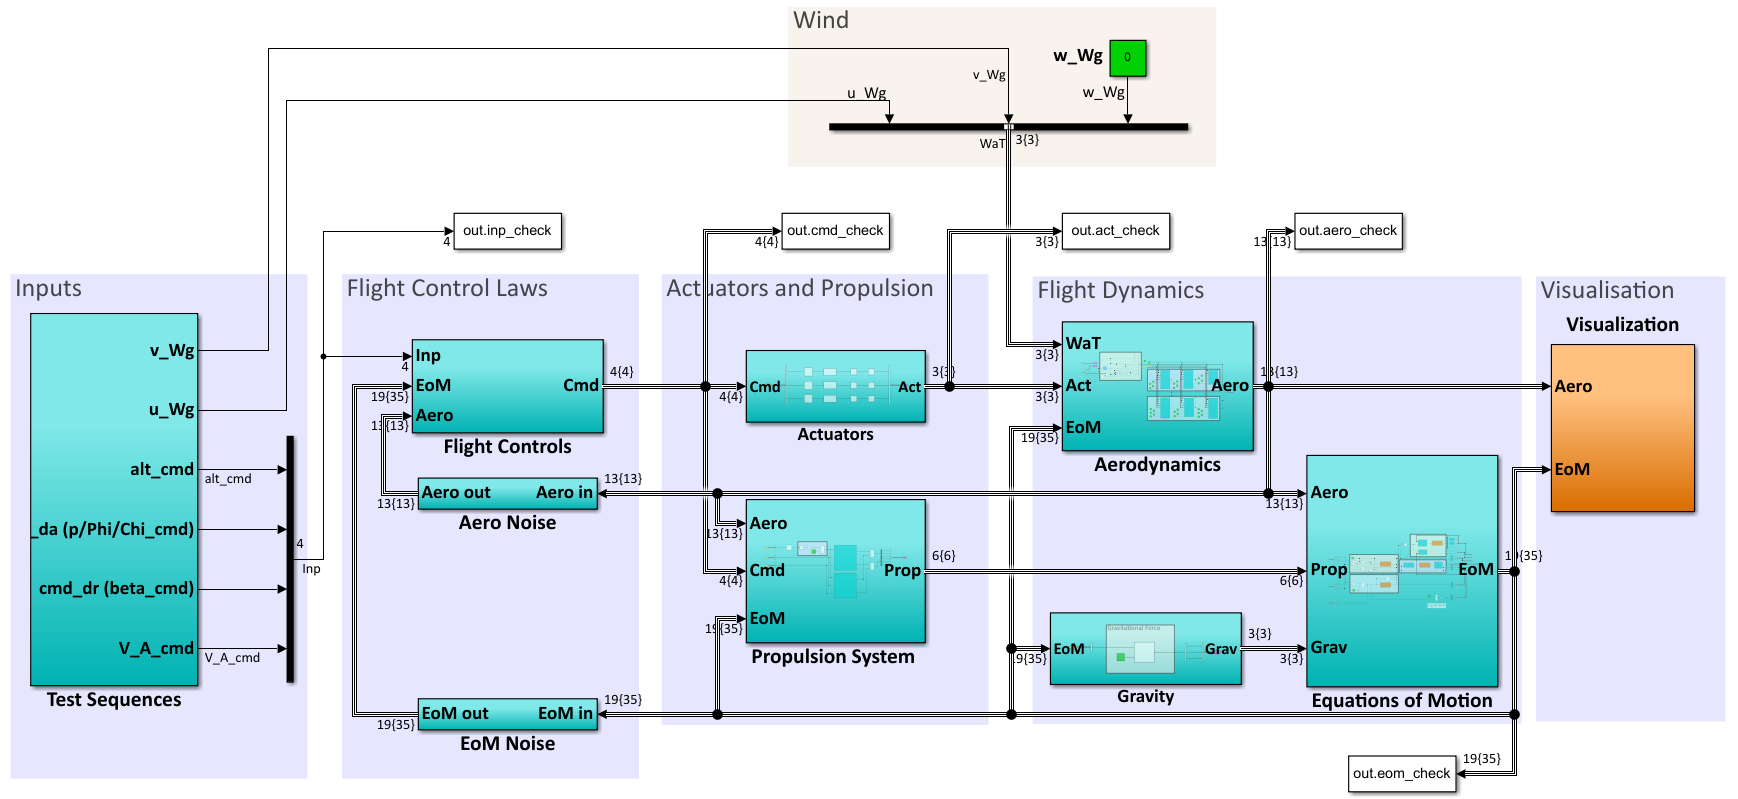

**Check**

run MyTrimStates.m

fprintf(['Trim State:' '\n' ...
'u   = ' num2str(MyTrimState_1.u) ' m/s' '\n' ...
'q   = ' num2str(MyTrimState_1.q) ' rad/s' '\n' ...
'Alt = ' num2str(MyTrimState_1.Alt) ' m'])
clear MyTrimState_1 MyTrimState_2 MyTrimState_3

run("AircraftParameters.m");
load("ControlLaws.mat")
TestSequence = 8;
[out] = sim('AircraftModel_6DoF_SAS.slx',20);

% Note that within the subsequent plots, we modify the units to ease
% interpretation. That is, rad -> deg, rad/s -> deg/s.
% Hence, ignore the units displayed in the labels

figure(430); clf
    subplot(3,2,1), plot(180/pi.*out.eom_check.OOmega_f.p,'k','linewidth',2), grid
    subplot(3,2,2), plot(180/pi.*out.eom_check.OOmega_f.r,'k','linewidth',2), grid
    subplot(3,2,3), plot(180/pi.*out.eom_check.PPhi.Phi,'k','linewidth',2), grid
    subplot(3,2,4), plot(180/pi.*out.aero_check.AirData.beta,'k','linewidth',2), grid
    subplot(3,2,5), plot(out.eom_check.Position.Alt,'k','linewidth',2), grid
    subplot(3,2,6), plot(out.aero_check.AirData.V_A,'k','linewidth',2), grid
clear out TestSequence

**Implement the SAS for the LDM**

We will now implement the SAS that you've designed in the previous tasks. All controllers (if not stated otherwise) will be implemented in the 'Lateral Directional Control Laws' subsystem within the 'Flight Controls' subsystem. We start with the yaw damper and then include the aileron-rudder-interconnection.

**Task 14:** implement the yaw damper and the ARI

- implement the yaw damper including the lowpass filter and the washout filter (use the provided block from the 'Auxiliary_Models.slx', do not forget the proportional gain 'kr'!) - parameterize the blocks appropriately

- implement the ARI: use the provided subsystem from the 'Auxiliary_Models.slx' and parameterize it

- **save** the 'AircraftModel_6DoF_SAS.slx' model

- simulate the aircraft's response using the subsequent check section - it simulates a horizontal $|V_\text{W}| =30\,\text{m/s}$ gust from the east (i.e. $\chi_\text{W} = 90^^\circ$, note that the aircraft's heading is $\Psi=60^^\circ$ ) with a duration of $25\,\text{s}$ beginning after $t=5\,\text{s}$ and an additional step input of $\delta_\text{r,cmd} = 5^^\circ$ rudder deflection after $t=40\,\text{s}$

- investigate the aircrafts response with and without the SAS active: compare the effect of the SAS on $p$, $r$, $\Phi$ and $\beta$ 

- compare the results to the plots from the check section after **Task 12**

Note that the gust has a higher impact on $p$ and $\Phi$ with the SAS switched on. This is counterintuitive as the SAS is designed to enhance stability. Note however, that the SAS you've designed comprises yaw rate feedback only. Recall from the lecture notes that a yaw damper can affect the roll subsidence pole, i.e., it reduces the roll damping of the aircraft. As there is no additional roll damper included in your SAS, the gust as a slightly increased effect on the roll motion than without the SAS. We consider this minor effect acceptable here.  

**Check**

load("ControlLaws.mat")

TestSequence = 1;
ControlLaws.LatDirMot.SAS.kr = 0;
ControlLaws.LatDirMot.SAS.ARI = eye(2);
[out] = sim('AircraftModel_6DoF_SAS.slx',50);

% Note that within the subsequent plots, we modify the units to ease
% interpretation. That is, rad -> deg, rad/s -> deg/s.
% Hence, ignore the units displayed in the labels

figure(431); clf
    subplot(3,2,1), plot(180/pi.*out.eom_check.OOmega_f.p,'k','linewidth',2), grid
    subplot(3,2,2), plot(180/pi.*out.eom_check.OOmega_f.r,'k','linewidth',2), grid
    subplot(3,2,3), plot(180/pi.*out.eom_check.PPhi.Phi,'k','linewidth',2), grid
    subplot(3,2,4), plot(180/pi.*out.aero_check.AirData.beta,'k','linewidth',2), grid
    subplot(3,2,5), plot(out.eom_check.Position.Alt,'k','linewidth',2), grid
    subplot(3,2,6), plot(out.aero_check.AirData.V_A,'k','linewidth',2), grid
clear out
    
load 'ControlLaws.mat'
[out] = sim('AircraftModel_6DoF_SAS.slx',50);
figure(431);
    subplot(3,2,1), hold on, grid on, plot(180/pi.*out.eom_check.OOmega_f.p,'r','linewidth',2),
    subplot(3,2,2), hold on, grid on, plot(180/pi.*out.eom_check.OOmega_f.r,'r','linewidth',2),
    subplot(3,2,3), hold on, grid on, plot(180/pi.*out.eom_check.PPhi.Phi,'r','linewidth',2),
    subplot(3,2,4), hold on, grid on, plot(180/pi.*out.aero_check.AirData.beta,'r','linewidth',2),legend('no SAS','Yaw Damper + ARI', 'location','north west')
    subplot(3,2,5), hold on, grid on, plot(out.eom_check.Position.Alt,'r','linewidth',2),
    subplot(3,2,6), hold on, grid on, plot(out.aero_check.AirData.V_A,'r','linewidth',2),
clear out TestSequence

**Sideslip Angle Control**

With the SAS implemented we now focus on the primary flight control laws for the lateral directional motion. Like in Part II for the longitudinal motion, you will use the loopshaping technique to design all contollers. 

Recall from the lecture (notes) that an aerodynamically clean flight ($\beta = 0^^\circ$) is desired to reduce drag and to keep the longitudinal motion and the LDM decoupled in order to simplify control. We thus start with a sideslip angle control loop.

**Task 15: **design the sideslip angle controller

- load the 'LinearLatModel_SAS' into your workspace

- use the `controlSystemDesigner` command to investigate the transfer function from rudder input to $\beta$

- apply the loopshaping technique to design the sideslip angle controller $K_\beta$

- as an orientation, try to achieve the following: **1)** zero steady state error **2)** settling time $(\pm 2\%)$$<5.5\,\text{s}$ **3)** overshoot $<10\%$ **4)** rise time $(80\,\%)$$<1.5\,\text{s}$ **5)** phase margin $PM>60^\circ$, **6)** gain margin $GM>6\,\text{db}$, **7) **$|L| >20\,\text{db}$ for $omega < 0.1\,\text{rad/s}$ **8)**$|L|<-30\,\text{db}$ for $\omega > 10\,\text{rad/s}$

- integrate a roll-off filter 'Kr' that reduces the loop gain $|L|$ for frequencies above $30\,\text{rad/s}$

- uncomment the subsequent code section and augment it with the results you obtained in the 'Control System Designer' app - hint: the provided code can be used as a guideline, comment out those controller stages that you don't need

- run this section such that the 'ControlLaws'-struct will be augmented

- save the augmented 'ControlLaws'-struct (overwrite the existing 'ControlLaws.mat')

- **save the changes you've made within this livescript**

- check the loopshape of $|L|$ using the subsequent check section. Note that minor violations of the bounds are in general of no significant importance 

load 'ControlLaws.mat'
clear Kp Ki Kr Kl
% --------------------start of your code -------------------------- %

% ControlLaws.LatDirMot.AoS.Kp  = ...;
% ControlLaws.LatDirMot.AoS.Ki  = ...;
% ControlLaws.LatDirMot.AoS.Klz = ...; % lead/lag compensator: location of the zero
% ControlLaws.LatDirMot.AoS.Klp = ...; % lead/lag compensator: location of the pole
% ControlLaws.LatDirMot.AoS.Kr  = ...;
% 
% s = tf('s');
% 
% Kp = ControlLaws.LatDirMot.AoS.Kp;
% Kr = ControlLaws.LatDirMot.AoS.Kr/(s+ControlLaws.LatDirMot.AoS.Kr);
% Kl = (s + ControlLaws.LatDirMot.AoS.Klz)/(s + ControlLaws.LatDirMot.AoS.Klp);
% Ki = (s + ControlLaws.LatDirMot.AoS.Ki)/s;
% Kbeta = zpk(Ki*Kr*Kl*Kp) % e.g. zpk(Ki*Kr*Kl*Kp) if all controller parts are used
% Kbeta = ss(Kbeta);
% Kbeta.InputName = 'e_beta'; Kbeta.InputUnit = '-';
% Kbeta.OutputName = 'cmd_dr'; Kbeta.OutputUnit = 'rad';
% Kbeta.StateName = {'K_beta','K_beta'};
% Kbeta.StateUnit = {'rad','rad'};
% ControlLaws.LatDirMot.AoS.Kbeta = Kbeta;

% --------------------end of your code ---------------------------- %
clear Kp Ki Kr Kl

**Check**

L = LinearLatModel_SAS('beta','cmd_dr')*ControlLaws.LatDirMot.AoS.Kbeta;
figure(433), clf, checkloopshape(L,20,0.1,-30,10)

**Task 16:** close the angle of sideslip feedback loop

- close the sideslip angle feedback loop for the 'LinearLatModel_SAS' using the `feedback` command. Make sure that the loop connects the correct model output to the correct model input

- specify the input names of both signals to 'cmd_da' and 'beta_cmd' - if necessary, update the input units

- name the newly created model 'LinearLonModel_beta' and save it to 'TrimState_1_LinearLatModel_beta.mat'

- check the stability margins of the closed loop system and its reaction to a step input using the subsequent check section

**Check**

load TrimState_1_LinearLatModel_beta
figure(434), clf, step(LinearLatModel_beta({'beta','p','r','n_y'},'beta_cmd'),10), grid
allmargin(LinearLatModel_beta('beta','beta_cmd')) % note that the gain margin is given in absolute gain (not in dB)

**Implement Sideslip Angle Controller**

**Task 17:** implement the sideslip angle controller into the nonlinear aircraft simulation model

- open the 'AircraftModel_6DoF_SAS.slx' model and ensure that it is executable

- close the angle of sideslip feedback loop and implement the sideslip angle controller into the 'Flight Controls/Lateral Directional Control Laws' subsystem - use the "controller modules" provided in the 'Auxiliary_Models.slx' model

- parameterize all blocks of the controller appropriately. Give every state within the 'Kbeta' controller the name 'Kbeta'

- initialize the last integrator in the series connection such that the trim rudder deflection is issued

- saturate the controller output such that the rudder deflection is limited to its maximum and minimum as specified within the 'AircraftParameters.m' script - don't use the 'Limit output' function of the integrator block!

- add anti-windup compensation using the 'Conditional Integration Anti Windup' block

- **save** the augmented model **to a new file** named 'AircraftModel_6DoF_AoS.slx'

- simulate the aircraft's response using the subsequent check section - it simulates a gust identical to the one used in **Task 14 **and an additional step command to $\beta_\text{cmd} = 6^^\circ$ issued after $t=40\,\text{s}$

- investigate the aircrafts response to the gust and the step input: does the aircraft track the$\beta$ command after the step input?

- reduce the commanded sidelip angle to $\beta_\text{cmd} = 3^^\circ$ and rerun the simulation: does the aircraft track the$\beta$ command after the step input now?

So what happend? Obviously, in the first simulation run, the rudder was deflected to its maximum and thus the commanded sideslip angle couldn't be tracked. In the second simulation run, where the commanded $\beta$ was reduced, tracking was possible. But how can we take actuator limitations into account already during the controller design? Recall section 7.6 of the lecture notes and the discussion on the control sensitivity $KS = K/(1+KP)$. To acknowledge actuator limitations, we can use equation 7.16 which links the peak magnitude of $KS$, the maximum control signal $\delta_\text{max}$ (in our example, the rudder deflection) and the amplitude of the reference signal $R_0$. Equation 7.18 can be used to account for rate limitations as $|K(j\omega)S(j\omega)| \leq \dot{\delta}_\text{max}/(\omega R_0)$. Uncomment the subsequent code section and run it to investigate the situation for $\beta_\text{cmd} = 6^^\circ$.

r_beta = deg2rad(6);
figure(435);clf; plotKSreq(LinearLatModel_SAS('beta','cmd_dr'),ControlLaws.LatDirMot.AoS.Kbeta,min(abs(Actuators.Limits.u_max_Hr)),min(abs(Actuators.RateLimits.udot_max_Hr)),r_beta); clear r_beta

We see that the saturation limit of the rudder is violated, not only for frequencies above the loop crossover but also for low frequencies. Now create the same plot for $\beta_\text{cmd} = 3^^\circ$ (simply modify `r_beta` and rerun this section). It is evident, that in the latter case, the saturation limits of the rudder are not violated. Hence, the sideslip angle controller is able to track a $\beta_\text{cmd} = 3^^\circ$ command but cannot track a $\beta_\text{cmd} = 6^^\circ$ reference because of insufficient control authority. As an indicator, you can rearrange equation 7.16 to compute $R_0 \leq \delta_\text{max}/max(|KS|)$. This is done with the code below. Note however, that the peak magnitude of $KS$ can be outside the frequency range of interest, i.e., at frequencies far above the bandwidth of the control loop under investigation.

[magKS,~,~]=bode(feedback(ControlLaws.LatDirMot.AoS.Kbeta,LinearLatModel_SAS('beta','cmd_dr'))); % get the magnitude plot for KS
KS_peak = mag2db(max(magKS)) % find the peak magnitude of KS in db
R_0 = rad2deg(min(abs(Actuators.Limits.u_max_Hr))/db2mag(KS_peak)) % maximum amplitude of a sinusoid reference signal that can (theoretically) be tracked by the controller
clear R_0 KS_peak magKS

**Check**

Remark: in case you receive error messages realted to solver problems, try the following: 1) open the simulink model 2) open the 'Model Settings' within the 'Modeling' tab of Simulink 3) select a different Variable-step solver, e.g. 'ode45 (Dormand-Prince) 4) click 'ok' and rerun this section

load 'ControlLaws.mat'
TestSequence = 2;
beta_cmd = deg2rad(6);

% Note that within the subsequent plots, we modify the units to ease
% interpretation. That is, rad -> deg, rad/s -> deg/s.
% Hence, ignore the units displayed in the labels

simulate_lat('AircraftModel_6DoF_AoS.slx',50,'dr',Actuators)
clear TestSequence

**Roll Rate Control**

The next step we take towards a complete lateral directional flight control system is a roll rate control loop. The roll rate controller $K_{pp}$ is the inner most controller within the cascaded control architecture for the LDM, recall figure 12.4 of the lecture notes. We intend to limit the maximum roll rate to $p=12.5\,^^\circ/s$ to ensure passenger comfort.

**Task 18: **design the roll rate controller

- load the 'LinearLatModel_beta' into your workspace

- use the `controlSystemDesigner` command to investigate the transfer function from aileron input to $p$

- apply the loopshaping technique to design the roll rate controller $K_{pp}$

- as an orientation, try to achieve the following: **1)** zero steady state error **2)** settling time $(\pm 2\%)$$<0.75\,\text{s}$ **3)** overshoot $<10\%$ **4)** rise time $(80\,\%)$$<0.3\,\text{s}$ **5)** phase margin $PM>60^\circ$, **6)** gain margin $GM>6\,\text{db}$, **7) **$|L| >20\,\text{db}$ for $\omega < 0.5\,\text{rad/s}$ **8)**$|L|<-20\,\text{db}$ for $\omega > 30\,\text{rad/s}$

- integrate a roll-off filter 'Kr' that reduces the loop gain $|L|$ for frequencies above $30\,\text{rad/s}$

- uncomment the subsequent code section and augment it with the results you obtained in the 'Control System Designer' app - hint: the provided code can be used as a guideline, comment out those controller stages that you don't need

- run this section such that the 'ControlLaws'-struct will be augmented

- save the augmented 'ControlLaws'-struct (overwrite the existing 'ControlLaws.mat')

- **save the changes you've made within this livescript**

- check the loopshape of $|L|$ using the subsequent check section

load 'ControlLaws.mat'
clear Kp Ki Kr Kl
% --------------------start of your code -------------------------- %

% ControlLaws.LatDirMot.RollRate.Kp  = ...;
% ControlLaws.LatDirMot.RollRate.Ki  = ...;
% ControlLaws.LatDirMot.RollRate.Klz = ...; % lead/lag compensator: location of the zero
% ControlLaws.LatDirMot.RollRate.Klp = ...; % lead/lag compensator: location of the pole
% ControlLaws.LatDirMot.RollRate.Kr  = ...;
% 
% s = tf('s');
% 
% Kp = ControlLaws.LatDirMot.RollRate.Kp;
% Kr = ControlLaws.LatDirMot.RollRate.Kr/(s+ControlLaws.LatDirMot.RollRate.Kr);
% Kl = (s + ControlLaws.LatDirMot.RollRate.Klz)/(s + ControlLaws.LatDirMot.RollRate.Klp);
% Ki = (s + ControlLaws.LatDirMot.RollRate.Ki)/s;
% Kpp = zpk(Ki*Kr*Kl*Kp) % e.g. zpk(Ki*Kr*Kl*Kp) if all controller parts are used
% Kpp = ss(Kpp);
% Kpp.InputName = 'e_p'; Kpp.InputUnit = 'rad/s';
% Kpp.OutputName = 'cmd_da'; Kpp.OutputUnit = 'rad';
% Kpp.StateName = {'K_pp','K_pp'};
% 
% ControlLaws.LatDirMot.RollRate.Kpp = Kpp;

% --------------------end of your code ---------------------------- %
clear Kp Ki Kr Kl

**Check**

L = LinearLatModel_beta('p','cmd_da')*ControlLaws.LatDirMot.RollRate.Kpp;
figure(440), clf, checkloopshape(L,20,0.5,-20,30)

**Task 19:** close the roll rate feedback loop

- close the roll rate feedback loop for the 'LinearLatModel_beta' using the `feedback` command. Make sure that the loop connects the correct model output to the correct model input

- specify the input names of both signals to 'p_cmd' and 'beta_cmd'  - if necessary, update the input units

- name the newly created model 'LinearLonModel_p' and save it to 'TrimState_1_LinearLatModel_p.mat'

- check the response of the closed loop system to step inputs using the subsequent check section

load TrimState_1_LinearLatModel_p
figure(441); clf; step(LinearLatModel_p({'p','r','Phi','beta','Chi'},{'p_cmd','beta_cmd'})*blkdiag(deg2rad(10),deg2rad(3)),10), grid

**Implement Roll Rate Controller**

**Task 20:** implement the roll rate controller into the nonlinear aircraft simulation model

- open the 'AircraftModel_6DoF_AoS.slx' model and ensure that it is executable

- close the roll rate feedback loop and implement the roll rate controller into the 'Flight Controls/Lateral Directional Control Laws' subsystem - use the "controller modules" provided in the 'Auxiliary_Models.slx' model

- parameterize all blocks of the controller appropriately. Give every state within the roll rate controller the name 'Kpp'

- initialize the last integrator in the series connection such that the trim aileron deflection is issued

- saturate the controller output such that the aileron deflection is limited to its maximum and minimum as specified within the 'AircraftParameters.m' script - don't use the 'Limit output' function of the integrator block!

- add anti-windup compensation using the 'Conditional Integration Anti Windup' block

- **save** the augmented model **to a new file** named 'AircraftModel_6DoF_p.slx'

- simulate the aircraft's response using the subsequent check section - two simulations are performed: in both simulation runs, a sinusoid roll rate reference command with an amplitude of $p_\text{cmd,max}=12.5\,^^\circ/s$ is issued. The frequency of the sinusoid reference is $\omega = 5\,\text{rad/s}$ for the first run and  $\omega = 2\,\text{rad/s}$for the second run.

- investigate the aircrafts responses to the sinusoid inputs: does the aircraft track the reference signals?

Again, we face actuator limitations in the case of the higher frequency sinusoid reference. Like in the case of the sideslip angle controller, we see that the roll rate controller issues control signals $\delta_\text{a,cmd}$ that - if not limited by us - would exceed the realizable aileron deflections. Moreover, it is evident, that the ailerons can't deflect as fast as the roll rate controller demands to track the reference signal. Hence, the control signal violates the rate limits $\dot{\delta}_\text{a,max}$ of the ailerons. Again, we can investigate the magnitude plot of the control sensitivity $KS$ to see that this is indeed the case for the high frequency sinusoid reference. Run the subsequent code to plot the magnitude plot of the control sensitivity $KS$.

r_p = deg2rad(12.5);
figure(442); clf; plotKSreq(LinearLatModel_beta('p','cmd_da'),ControlLaws.LatDirMot.RollRate.Kpp,min(abs(Actuators.Limits.u_max_Ha)),min(abs(Actuators.RateLimits.udot_max_Ha)),r_p)

From the magnitude plot we see that the rate limits of the actuation system aren't violated for sinusoid inputs (for $p_\text{cmd,max}=12.5\,^^\circ/s$ !) of frequencies up to $\omega \approx 2\,\text{rad/s}$. This matches the observations we make in the second simulation run where $\omega = 2\,\text{rad/s}$. So despite the fact that the roll rate control loop has a closed loop bandwidth of $\omega_b \approx 5\,\text{rad/s}$ (or more), limitations of the actuation system can make reference tracking for signals of this frequency impossible. Note however, that sinusoid inputs are not a typical reference for a flight controller. Further note that a faster control loop (i.e. a higher closed loop bandwidth) still provides faster responses. The important thing here is, that the pilot (or the next outer control loop) should not issue reference signals such that the acuation system is overloaded.

**Check**

Remark: in case you receive error messages related to solver problems, try the following: 1) open the simulink model 2) open the 'Model Settings' within the 'Modeling' tab of Simulink 3) select a different Variable-step solver, e.g. 'ode45 (Dormand-Prince) 4) click 'ok' and rerun this section

load 'ControlLaws.mat'
ampl_p_cmd = deg2rad(12.5);
omega_p_cmd = 5;
TestSequence = 3;

% Note that within the subsequent plots, we modify the units to ease
% interpretation. That is, rad -> deg, rad/s -> deg/s.
% Hence, ignore the units displayed in the labels

simulate_lat('AircraftModel_6DoF_p.slx',5,'da',Actuators)

ampl_p_cmd = deg2rad(12.5);
omega_p_cmd = 2;

simulate_lat('AircraftModel_6DoF_p.slx',5,'da',Actuators)
clear TestSequence ampl_p_cmd omega_p_cmd

**Bank Angle Control**

Recall from the lecture (notes) that the bank-to-turn maneuver is the preferable way of changing the aircrafts direction of flight. Hence, the next outer loop of the cascaded LDM control architecture is the bank angle controller $K_\Phi$.

**Task 21: **design the bank angle controller

- load the 'LinearLatModel_p' model into your workspace

- use the `controlSystemDesigner` command to investigate the transfer function from input 'p_cmd' to 'Phi'

- apply the loopshaping technique to design the bank angle controller $K_{\Phi}$

- as an orientation, try to achieve the following: **1)** steady state error $<2\%$ **2)** settling time $(\pm 2\%)$$<3\,\text{s}$ **3)** no overshoot  **4)** rise time $(80\,\%)$$<1.75\,\text{s}$ **5)** phase margin $PM>60^\circ$, **6)** gain margin $GM>6\,\text{db}$, **7) **$|L| >20\,\text{db}$ for $\omega < 0.1\,\text{rad/s}$ **8)**$|L|<-20\,\text{db}$ for $\omega > 10\,\text{rad/s}$

- limit the bandwidth to less than $2\,\text{rad/s}$ such that the computed reference signals to the roll rate controller do not lead to an overwhelmed acutation system 

- integrate a roll-off filter 'Kr' that reduces the loop gain $|L|$ for frequencies above $30\,\text{rad/s}$

- uncomment the subsequent code section and augment it with the results you obtained in the 'Control System Designer' app - hint: the provided code can be used as a guideline, comment out those controller stages that you don't need

- run this section such that the 'ControlLaws'-struct will be augmented

- save the augmented 'ControlLaws'-struct (overwrite the existing 'ControlLaws.mat')

- **save the changes you've made within this livescript**

- check the loopshape of $|L|$ using the subsequent check section

load 'ControlLaws.mat'
clear Kp Ki Kr Kl
% --------------------start of your code -------------------------- %

% ControlLaws.LatDirMot.BankAngle.Kp  = ...;
% ControlLaws.LatDirMot.BankAngle.Ki  = ...;
% ControlLaws.LatDirMot.BankAngle.Klz = ...; % lead/lag compensator: location of the zero
% ControlLaws.LatDirMot.BankAngle.Klp = ...; % lead/lag compensator: location of the pole
% ControlLaws.LatDirMot.BankAngle.Kr = ...;
% 
% s = tf('s');
% 
% Kp = ControlLaws.LatDirMot.BankAngle.Kp;
% Kr = ControlLaws.LatDirMot.BankAngle.Kr/(s+ControlLaws.LatDirMot.BankAngle.Kr);
% Kl = (s + ControlLaws.LatDirMot.BankAngle.Klz)/(s + ControlLaws.LatDirMot.BankAngle.Klp);
% Ki = (s + ControlLaws.LatDirMot.BankAngle.Ki)/s;
% KPhi = zpk(Ki*Kr*Kl*Kp) % e.g. zpk(Ki*Kr*Kl*Kp) if all controller parts are used
% KPhi = ss(KPhi);
% KPhi.InputName = 'e_Phi'; KPhi.InputUnit = 'rad';
% KPhi.OutputName = 'p_cmd'; KPhi.OutputUnit = 'rad/s';
% KPhi.StateName = {'K_Phi'};
% 
% ControlLaws.LatDirMot.BankAngle.KPhi = KPhi;
% 
% ControlLaws.Saturations.p = [deg2rad(-12.5), deg2rad(12.5)];

% --------------------end of your code ---------------------------- %
clear Kp Ki Kr Kl

**Check**

L = LinearLatModel_p('Phi','p_cmd')*ControlLaws.LatDirMot.BankAngle.KPhi;
figure(450), clf, checkloopshape(L,20,0.1,-20,10)

**Task 22:** close the bank angle feedback loop

- close the bank angle feedback loop for the 'LinearLatModel_p' model using the `feedback` command. Make sure that the loop connects the correct model output to the correct model input

- specify the input names of both signals to 'Phi_cmd' and 'beta_cmd'  - if necessary, update the input units

- name the newly created model 'LinearLonModel_Phi' and save it to 'TrimState_1_LinearLatModel_Phi.mat'

- check the response of the closed loop system to step inputs using the subsequent check section

**Check**

load TrimState_1_LinearLatModel_Phi
figure(451); clf; step(LinearLatModel_Phi({'p','r','Phi','beta','Chi'},{'Phi_cmd','beta_cmd'})*blkdiag(deg2rad(20),deg2rad(3)),10), grid

**Implement Bank Angle Controller**

**Task 23:** implement the bank angle controller into the nonlinear aircraft simulation model

- open the 'AircraftModel_6DoF_p.slx' model and ensure that it is executable

- close the bank angle feedback loop and implement the bank angle controller into the 'Flight Controls/Lateral Directional Control Laws' subsystem - use the "controller modules" provided in the 'Auxiliary_Models.slx' model

- parameterize all blocks of the controller appropriately. Give every state within the bank angle controller the name 'KPhi'

- Saturate the controller output such that the commanded roll rate is limited to $p_\text{cmd,max}=\pm12.5\,^^\circ/s$

- **save** the augmented model **to a new file** named 'AircraftModel_6DoF_Phi.slx'

- simulate the aircraft's response using the subsequent code section - the following reference signals will be issued: a step input to $\Phi_\text{cmd} = 55^^\circ$ after $5\,\text{s}$ kept for $20\,\text{s}$, a step input to $\Phi_\text{cmd} = -55^^\circ$ after $25\,\text{s}$ again kept for $20\,\text{s}$, and a horizontal gust identical to the one used in **Task 14**

- investigate the aircrafts responses to the inputs: also take a look at the altitude during the turns.

**Check**

Remark: in case you receive error messages realted to solver problems, try the following: 1) open the simulink model 2) open the 'Model Settings' within the 'Modeling' tab of Simulink 3) select a different Variable-step solver, e.g. 'ode45 (Dormand-Prince) 4) click 'ok' and rerun this section

load 'ControlLaws.mat'
TestSequence = 4;
[out] = sim('AircraftModel_6DoF_Phi.slx',60);

% Note that within the subsequent plots, we modify the units to ease
% interpretation. That is, rad -> deg, rad/s -> deg/s.
% Hence, ignore the units displayed in the labels

figure(452); clf
    subplot(3,2,1), plot(180/pi.*out.eom_check.OOmega_f.p,'k','linewidth',2), grid
    subplot(3,2,2), plot(180/pi.*out.eom_check.TrackData.Chi,'k','linewidth',2), grid,
    subplot(3,2,3), plot(180/pi.*out.eom_check.PPhi.Phi,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,180/pi.*out.inp_check.Data(:,2),'k--','linewidth',2),
    subplot(3,2,4), plot(180/pi.*out.aero_check.AirData.beta,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,180/pi.*out.inp_check.Data(:,3),'k--','linewidth',2),
    subplot(3,2,5), plot(out.eom_check.Position.Alt,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,out.inp_check.Data(:,1),'k--','linewidth',2),
    subplot(3,2,6), plot(out.aero_check.AirData.V_A,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,out.inp_check.Data(:,4),'k--','linewidth',2),
clear out TestSequence

**Turn Compensation**

From the last section we see that the bank angle controller performs as intended, i.e., the aircraft changes its course ('Chi') due to non-zero bank angle. By banking the aircraft, the direction of the lift force vector is tilted as well. For high bank angles (as within the simulation above) the lift force cannot compensate gravity and the aircraft loses height. To reduce this effect we can implement a *turn compensation*. The turn compensation issues an additional load factor command subject to the current bank angle. The load factor controller will thus command additional elevator deflection to pitch up the aircraft and thus produce more lift. The additionally required load factor to compensate for the turn can be computed to $\Delta n_{z,\text{TC}} = 1 - \cos(\Theta)/\cos(\Phi)$. It must be added to the load factor command computed by the climb rate controller.

**Task 24:** add turn compensation to the nonlinear simulation model

- open the 'AircraftModel_6DoF_Phi.slx' model an ensure that it is executable

- implement and complete the 'Turn Compesation' block from the 'Auxiliary_Models.slx' into the load factor controller

- run the subsequent code and compare the results (especially with respect to the altitude response of the aircraft)

load 'ControlLaws.mat'
TestSequence = 4;
TurnCompensation=0;

% Remark: in case you receive error messages realted to solver problems, try the following: 1) open the simulink model 2) open the 'Model Settings' within the 'Modeling' tab of Simulink 3) select a different Variable-step solver, e.g. 'ode45 (Dormand-Prince) 4) click 'ok' and rerun this section

[out] = sim('AircraftModel_6DoF_Phi.slx',60);

% Note that within the subsequent plots, we modify the units to ease
% interpretation. That is, rad -> deg, rad/s -> deg/s.
% Hence, ignore the units displayed in the labels

figure(453); clf
    subplot(3,2,1), plot(180/pi.*out.eom_check.OOmega_f.p,'k','linewidth',2), grid
    subplot(3,2,2), plot(180/pi.*out.eom_check.OOmega_f.r,'k','linewidth',2), grid
    subplot(3,2,3), plot(180/pi.*out.eom_check.PPhi.Phi,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,180/pi.*out.inp_check.Data(:,2),'k--','linewidth',2),
    subplot(3,2,4), plot(180/pi.*out.aero_check.AirData.beta,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,180/pi.*out.inp_check.Data(:,3),'k--','linewidth',2),
    subplot(3,2,5), plot(out.eom_check.Position.Alt,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,out.inp_check.Data(:,1),'k--','linewidth',2),
    subplot(3,2,6), plot(out.aero_check.AirData.V_A,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,out.inp_check.Data(:,4),'k--','linewidth',2),
 clear out
 
TurnCompensation=1;
[out] = sim('AircraftModel_6DoF_Phi.slx',60);

    subplot(3,2,1), grid, hold on, plot(180/pi.*out.eom_check.OOmega_f.p,'r','linewidth',2),
    subplot(3,2,2), grid, hold on, plot(180/pi.*out.eom_check.OOmega_f.r,'r','linewidth',2),
    subplot(3,2,3), grid, hold on, plot(180/pi.*out.eom_check.PPhi.Phi,'r','linewidth',2),
    subplot(3,2,4), grid, hold on, plot(180/pi.*out.aero_check.AirData.beta,'r','linewidth',2),
    subplot(3,2,5), grid, hold on, plot(out.eom_check.Position.Alt,'r','linewidth',2),
    subplot(3,2,6), grid, hold on, plot(out.aero_check.AirData.V_A,'r','linewidth',2),
clear out TestSequence

**Course Angle Control**

Finally, we want to include a second autopilot function to reduce the workload for the pilots: a course angle controller (the first autopilot function is the altitude controller of Part II). The course angle controller $K_\chi$ will compute bank angle commands that will then be tracked by the bank angle controller. Thus, we close the last cascade of the LDM control architecture.

**Task 25: **design a course angle controller

- load the 'LinearLatModel_Phi' model into your workspace

- use the `controlSystemDesigner` command to investigate the transfer function from input 'Phi_cmd' to 'Chi'

- apply the loopshaping technique to design the course angle controller $K_\chi$

- as an orientation, try to achieve the following: **1)** no steady state error **2)** settling time $(\pm 2\%)$$<7\,\text{s}$ **3)** overshoot $<1\%$  **4)** rise time $(80\,\%)$$<4.5\,\text{s}$ **5)** phase margin $PM>60^\circ$, **6)** gain margin $GM>6\,\text{db}$, **7) **$|L| >20\,\text{db}$ for $\omega < 0.03\,\text{rad/s}$ **8)**$|L|<-30\,\text{db}$ for $\omega > 5\,\text{rad/s}$

- limit the bandwidth to less than $0.8\,\text{rad/s}$ such that the computed reference signals to the roll rate controller do not lead to an overwhelmed acutation system 

- integrate a roll-off filter 'Kr' that reduces the loop gain $|L|$ for frequencies above $5\,\text{rad/s}$

- uncomment the subsequent code section and augment it with the results you obtained in the 'Control System Designer' app - hint: the provided code can be used as a guideline, comment out those controller stages that you don't need

- run this section such that the 'ControlLaws'-struct will be augmented

- save the augmented 'ControlLaws'-struct (overwrite the existing 'ControlLaws.mat')

- **save the changes you've made within this livescript**

- check the loopshape of $|L|$ using the subsequent check section

load 'ControlLaws.mat'
clear Kp Ki Kr Kl
% --------------------start of your code -------------------------- %

% ControlLaws.LatDirMot.Course.Kp  = ...;
% ControlLaws.LatDirMot.Course.Ki  = ...;
% ControlLaws.LatDirMot.Course.Klz = ...; % lead/lag compensator: location of the zero
% ControlLaws.LatDirMot.Course.Klp = ...; % lead/lag compensator: location of the pole
% ControlLaws.LatDirMot.Course.Kr  = ...;
% 
% s = tf('s');
% 
% Kp = ControlLaws.LatDirMot.Course.Kp;
% Kr = ControlLaws.LatDirMot.Course.Kr/(s+ControlLaws.LatDirMot.Course.Kr);
% Kl = (s + ControlLaws.LatDirMot.Course.Klz)/(s + ControlLaws.LatDirMot.Course.Klp);
% Ki = (s + ControlLaws.LatDirMot.Course.Ki)/s;
% KChi = zpk(Ki*Kr*Kl*Kp) % e.g. zpk(Ki*Kr*Kl*Kp) if all controller parts are used
% KChi = ss(KChi);
% KChi.InputName = 'e_Chi'; KChi.InputUnit = 'rad';
% KChi.OutputName = 'Phi_cmd'; KChi.OutputUnit = 'rad';
% KChi.StateName = {'K_Chi'};
% 
% ControlLaws.LatDirMot.Course.KChi = KChi;
% 
% ControlLaws.Saturations.Phi = [deg2rad(-40), deg2rad(40)];

% --------------------end of your code ---------------------------- %
clear Kp Ki Kr Kl

**Check**

load TrimState_1_LinearLatModel_Chi
L = LinearLatModel_Phi('Chi','Phi_cmd')*ControlLaws.LatDirMot.Course.KChi;
figure(450), clf, checkloopshape(L,20,0.03,-30,5)

**Task 26:** close the course angle feedback loop

- close the course angle feedback loop for the 'LinearLatModel_Phi' model using the `feedback` command. Make sure that the loop connects the correct model output to the correct model input

- specify the input names of both signals to 'Chi_cmd' and 'beta_cmd'  - if necessary, update the input units

- name the newly created model 'LinearLonModel_Chi' and save it to 'TrimState_1_LinearLatModel_Chi.mat'

- check the response of the closed loop system to step inputs using the subsequent check section

**Check**

figure(451); clf; step(LinearLatModel_Chi({'p','r','Phi','beta','Chi'},{'Chi_cmd','beta_cmd'})*blkdiag(deg2rad(30),deg2rad(3)),15), grid

**Implement Course Angle Controller**

**Task 27:** implement the course angle controller into the nonlinear aircraft simulation model

- open the 'AircraftModel_6DoF_Phi.slx' model and ensure that it is executable

- close the course angle feedback loop and implement the course angle controller into the 'Flight Controls/Lateral Directional Control Laws' subsystem - use the "controller modules" provided in the 'Auxiliary_Models.slx' model

- parameterize all blocks of the controller appropriately. Give every state within the course angle controller the name 'KChi'

- Saturate the controller output such that the commanded bank angle is limited to $\Phi_\text{cmd,max}=\pm 40\,^^\circ$

- **save** the augmented model **to a new file** named 'AircraftModel_6DoF_Chi.slx'

- simulate the aircraft's response using the subsequent check section - after $10\,\text{s}$ the pilot sets a new course angle $\chi_\text{cmd} = 350^^\circ$ for the autopilot to aquire, see the figure below. After $40\,\text{s}$ a horizontal gust from east, identical to the one used in **Task 14**, is disturbing the aircraft

- investigate the aircrafts response to the input: especially look at the course angle $\chi$

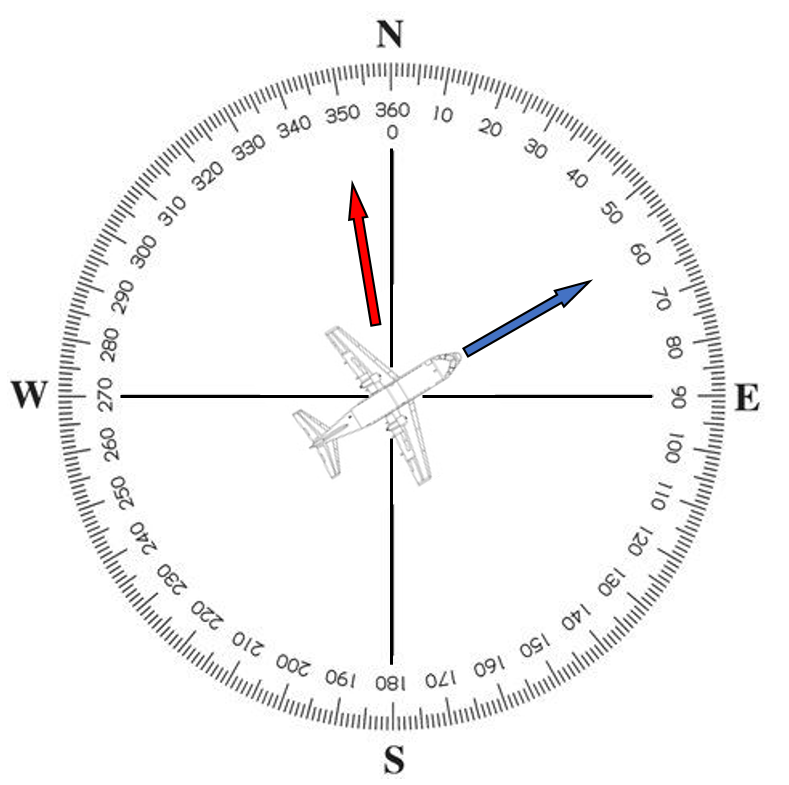

Note that the course angle controller commands a positive bank angle because $e_\chi = \chi_\text{cmd} - \chi >0\degree $. Hence, the aircraft flies a curve to the right eventhough this leads to a $290^^\circ$turn. Instead, a left curve of only $70^^\circ$ would be desireable. 

- add the 'Choose Shortest Turn' block from the 'Auxiliary_Models.slx' to the course angle controller

- rerun the simulation and compare the aircraft's response to the last simulation run

- save the 'AircraftModel_6DoF_Chi.slx'

**Check**

Remark: in case you receive error messages realted to solver problems, try the following: 1) open the simulink model 2) open the 'Model Settings' within the 'Modeling' tab of Simulink 3) select a different Variable-step solver, e.g. 'ode45 (Dormand-Prince) 4) click 'ok' and rerun this section

load("ControlLaws.mat")
TestSequence = 5;
[out] = sim('AircraftModel_6DoF_Chi.slx',100);

% Note that within the subsequent plots, we modify the units to ease
% interpretation. That is, rad -> deg, rad/s -> deg/s.
% Hence, ignore the units displayed in the labels

figure(487); clf
    subplot(3,2,1), plot(180/pi.*out.eom_check.OOmega_f.p,'k','linewidth',2), grid
    subplot(3,2,2), plot(180/pi.*out.eom_check.PPhi.Phi,'k','linewidth',2), grid,
    subplot(3,2,3), plot(180/pi.*out.aero_check.AirData.beta,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,180/pi.*out.inp_check.Data(:,3),'r--','linewidth',2),
    subplot(3,2,4), plot(180/pi.*out.eom_check.TrackData.Chi,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,180/pi.*out.inp_check.Data(:,2),'r--','linewidth',2),
    subplot(3,2,5), plot(out.eom_check.Position.Alt,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,out.inp_check.Data(:,1),'r--','linewidth',2),
    subplot(3,2,6), plot(out.aero_check.AirData.V_A,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,out.inp_check.Data(:,4),'r--','linewidth',2),
clear out TestSequence

**Final Test of the Autopilot**

Congratulations! Now, with the course angle control loop closed, you've completed the flight control system for both, the longitudinal and the lateral-directional motion! Run a final test to evaluate your flight control system.

**Final Task 28: **run a final test of the control system

- run this section and investigate the aircraft response

- also look at the issued control surface commands and the thrust lever position

- **optional**: check the system for a trim point that significantly differs from the linearization point you used for controller design - e.g. change the trim altitude from low to high (or vice versa) and the forward velocity from slow to fast (or vice verca), then rerun the simulation (note that the control surface deflections will not match the modified trim conditions - of course, you could easily trim the aircraft for the new operating point)

TestSequence = 6;
[out] = sim('AircraftModel_6DoF_Chi.slx',150);

% Note that within the subsequent plots, we modify the units to ease
% interpretation. That is, rad -> deg, rad/s -> deg/s.
% Hence, ignore the units displayed in the labels

figure(490); clf
    subplot(3,2,1), plot(180/pi.*out.eom_check.OOmega_f.p,'k','linewidth',2), grid
    subplot(3,2,2), plot(180/pi.*out.eom_check.PPhi.Phi,'k','linewidth',2), grid,
    subplot(3,2,3), plot(180/pi.*out.aero_check.AirData.beta,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,180/pi.*out.inp_check.Data(:,3),'r--','linewidth',2),
    subplot(3,2,4), plot(180/pi.*out.eom_check.TrackData.Chi,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,180/pi.*out.inp_check.Data(:,2),'r--','linewidth',2),
    subplot(3,2,5), plot(180/pi.*out.act_check.da,'k','linewidth',2), grid, hold on, plot(out.cmd_check.cmd_da.Time(1:ceil(numel(out.cmd_check.cmd_da.Time)/300):end),180/pi.*out.cmd_check.cmd_da.Data(1:ceil(numel(out.cmd_check.cmd_da.Data)/300):end),'r--','linewidth',2),
    subplot(3,2,6), plot(180/pi.*out.act_check.dr,'k','linewidth',2), grid, hold on, plot(out.cmd_check.cmd_dr.Time(1:ceil(numel(out.cmd_check.cmd_dr.Time)/300):end),180/pi.*out.cmd_check.cmd_dr.Data(1:ceil(numel(out.cmd_check.cmd_dr.Data)/300):end),'r--','linewidth',2),

figure(491); clf
    subplot(3,2,1), plot(180/pi.*out.eom_check.OOmega_f.q,'k','linewidth',2), grid
    subplot(3,2,2), plot(180/pi.*out.eom_check.PPhi.Theta,'k','linewidth',2), grid,
    subplot(3,2,3), plot(180/pi.*out.aero_check.AirData.alpha,'k','linewidth',2), grid,
    subplot(3,2,4), plot(out.eom_check.Position.Alt,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,out.inp_check.Data(:,1),'r--','linewidth',2),
    subplot(3,2,5), plot(180/pi.*out.act_check.de,'k','linewidth',2), grid, hold on, plot(out.cmd_check.cmd_de.Time(1:ceil(numel(out.cmd_check.cmd_de.Time)/300):end),180/pi.*out.cmd_check.cmd_de.Data(1:ceil(numel(out.cmd_check.cmd_de.Data)/300):end),'r--','linewidth',2),

figure(492); clf;
    subplot(2,1,1), plot(out.aero_check.AirData.V_A,'k','linewidth',2), grid, hold on, plot(out.inp_check.Time,out.inp_check.Data(:,4),'r--','linewidth',2),
    subplot(2,1,2), plot(out.cmd_check.cmd_dt,'k','linewidth',2), grid,
clear out TestSequence

% end of file